clear;
load('data2.mat');
mu = mean(Xval);
sigma2 = cov(Xval);
Xvalprobs = mvnpdf(Xval,mu,sigma2);
[Xroc,Yroc,T,auc,Opt] = perfcurve(yval,Xvalprobs,0);
Topt = T(Opt(1) == Xroc & Opt(2) == Yroc);
fprintf('Best epsilon found using ROC: %e\n', Topt);

Best epsilon found using ROC: 7.313641e-04


confusionmat(Xvalprobs < Topt,yval==1)

ans =    298     2
     0     7


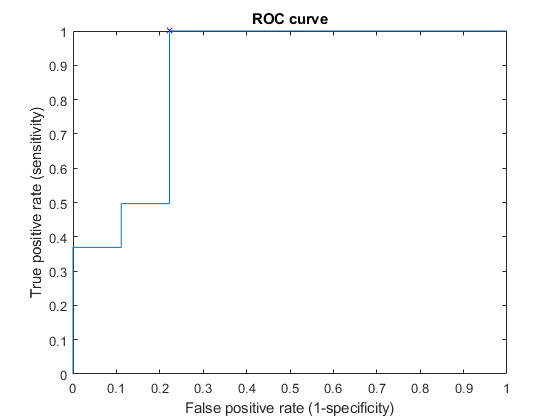

plot(Xroc,Yroc); hold on;
plot(Opt(1),Opt(2),'bx'); hold off;
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve'); 

fprintf('# of outliers predicted: %d',sum(mvnpdf(X,mu,sigma2) < Topt));

# of outliers predicted: 5